16.15

close all
clear
clc

s = tf('s');
mot.k = 2.8;
mot.T = 0.3;
pid.Kp = 6.2;
pid.Ki = 9.3;
pid.Kd = 1;

P = mot.k / (s * (mot.T * s + 1));
C = pid.Kp + pid.Ki / s + pid.Kd * s;

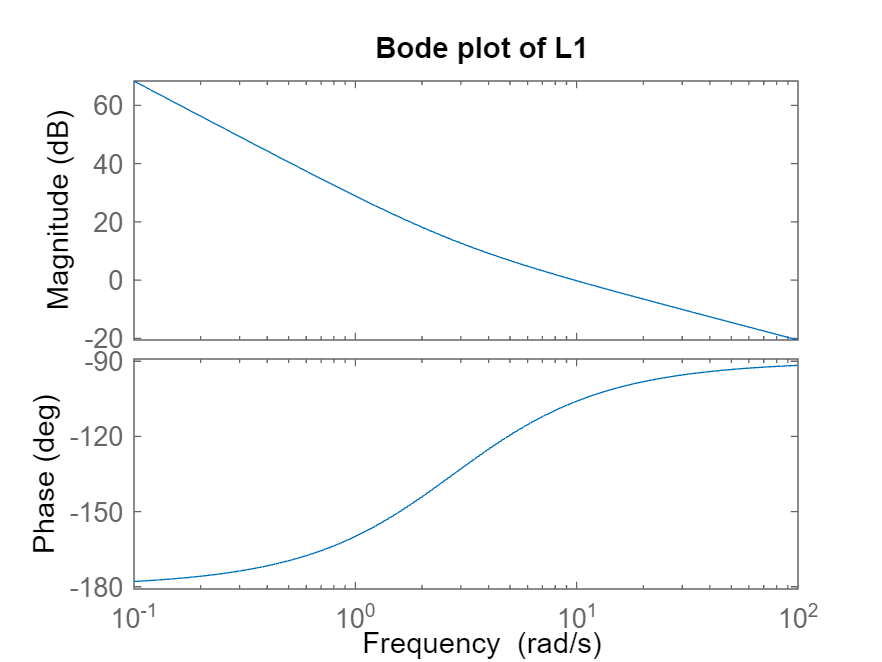

L1 = C * P;
close all
figure(1)
bode(L1)
title("Bode plot of L1")

[~, phim, ~, wgc] = margin(L1);

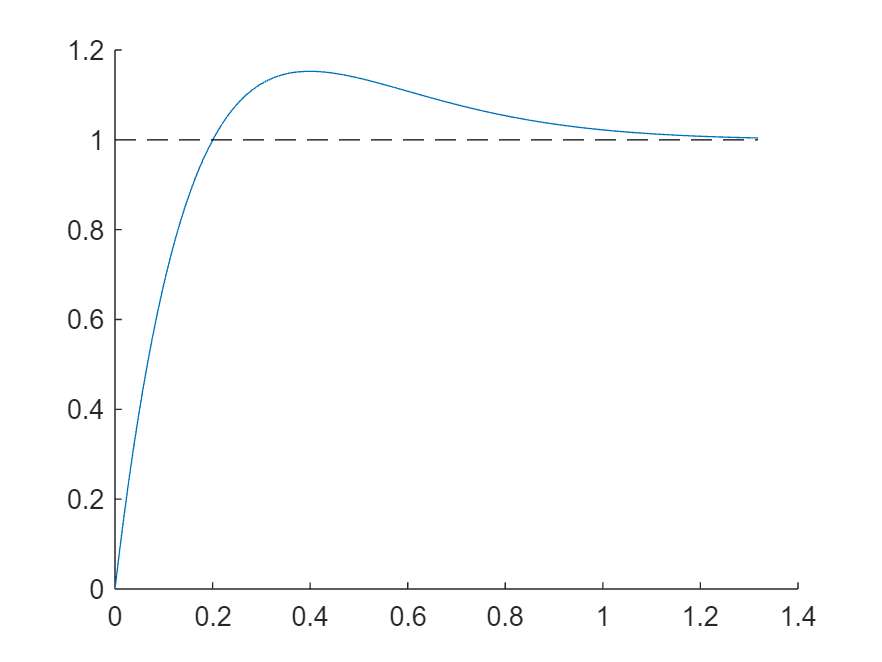

T1 = minreal(feedback(L1, 1), 1e-6);
[y1, t1] = step(T1);
close all
figure(2)
hold on
plot(t1, y1)
plot([t1(1), t1(end)], [1, 1], "k--")

stepinfo(y1, t1, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.1496
    TransientTime: 0.7975
     SettlingTime: 0.7975
      SettlingMin: 0.9084
      SettlingMax: 1.1526
        Overshoot: 14.7818
       Undershoot: 0
             Peak: 1.1526
         PeakTime: 0.4011


wn = 41.2;
d = 0.05;

G = wn^2 / (s^2 + 2 * d * wn * s + wn^2);
P1 = P * G;
L2 = C * P1;
T2 = minreal(feedback(L2, 1), 1e-6);

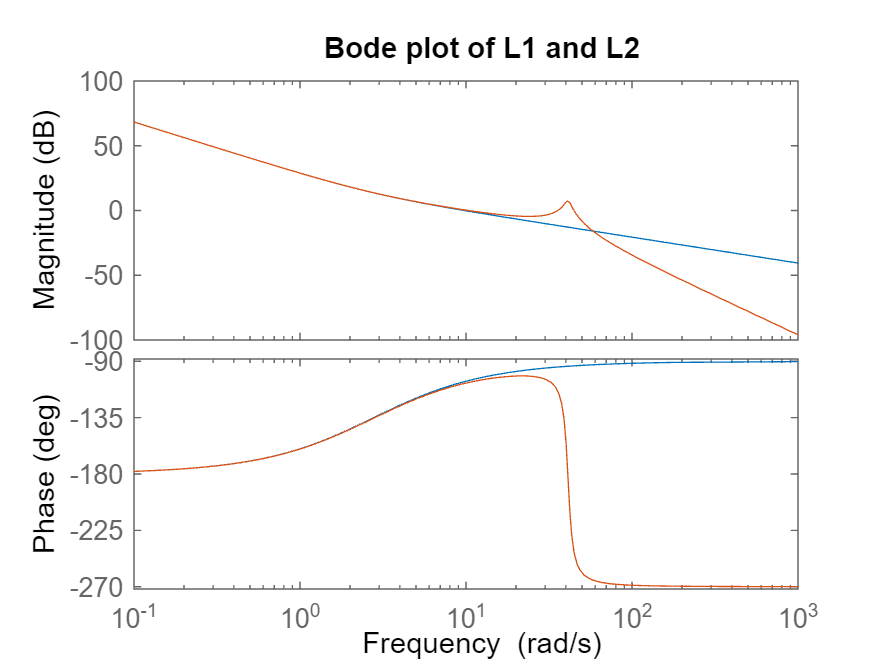

close all
figure(3)
hold on
bode(L1, "r")
bode(L2, "g")
legend("L1", "L2")
title("Bode plot of L1 and L2")

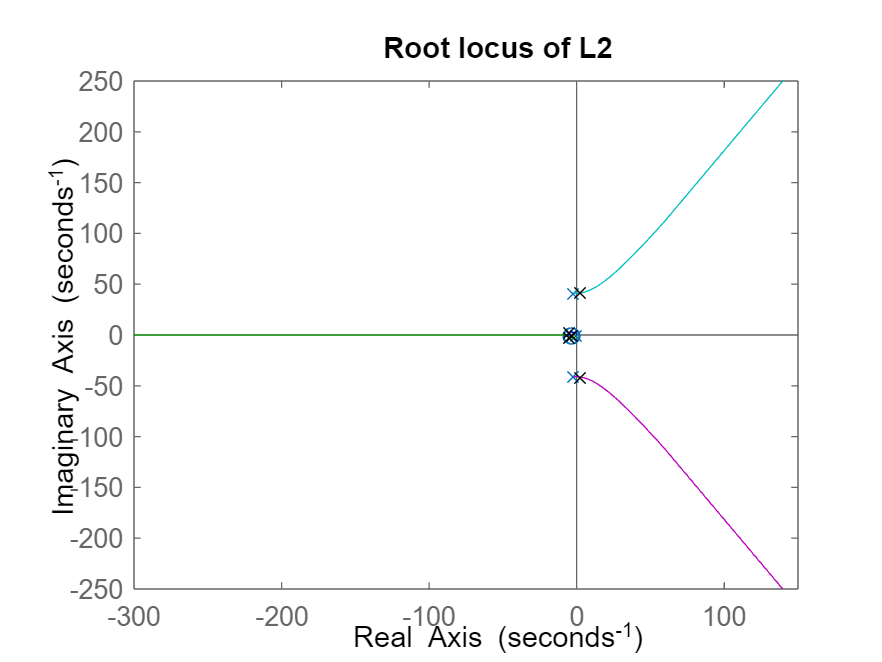

close all
poles1 = pole(T2);
figure(4)
hold on
rlocus(L2)
plot(real(poles1), imag(poles1), "kx")
title("Root locus of L2")

Il sistema in catena chiusa così ottenuto non è BIBO stabile, in quanto presenta due poli a parte reale positiva.

kbar = margin(L2)

kbar = 0.4383

dz = 0.1;
dp = 0.9;
w0 = wn;

N = (s^2 + 2 * dz * w0 * s + w0^2) / (s^2 + 2 * dp * w0 * s + w0^2);
C1 = C * N;
L3 = C1 * P1;
T3 = minreal(feedback(L3, 1), 1e-6);

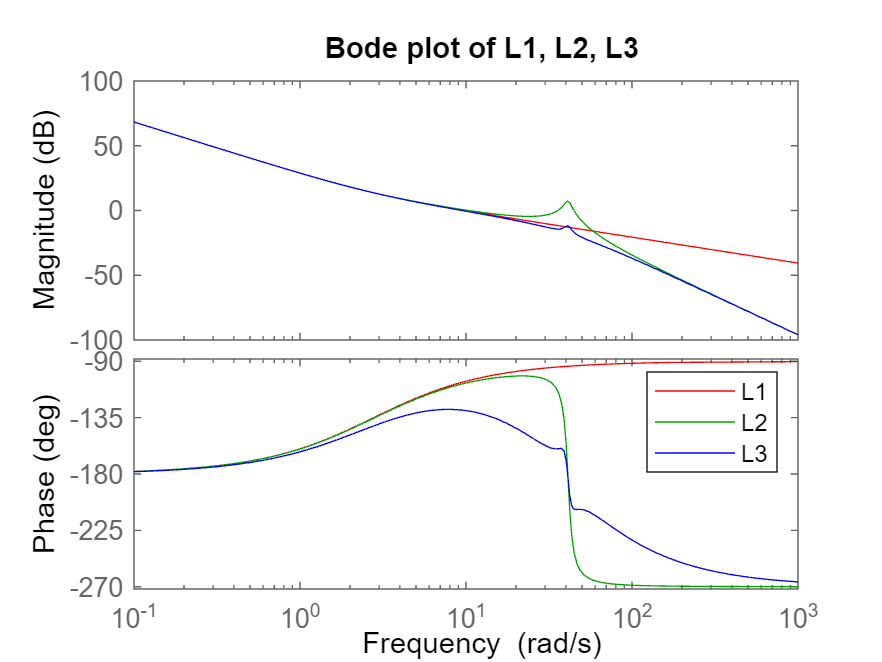

close all
figure(5)
hold on
bode(L1, "r")
bode(L2, "g")
bode(L3, "b")
title("Bode plot of L1, L2, L3")
legend("L1", "L2", "L3")

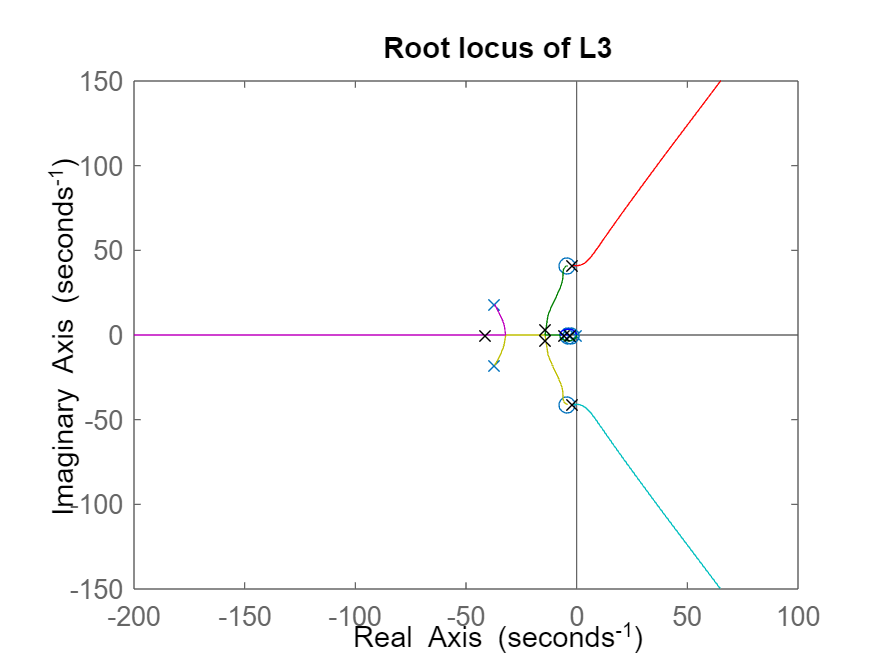

close all
poles2 = pole(T3);
figure(6)
hold on
rlocus(L3)
plot(real(poles2), imag(poles2), "kx")
title("Root locus of L3")

Tutti i poli hanno parte reale negativa, dunque il sistema è BIBO stabile.

[~, phim2, ~, wgc2] = margin(L3)

phim2 = 51.0415

wgc2 = 9.4636

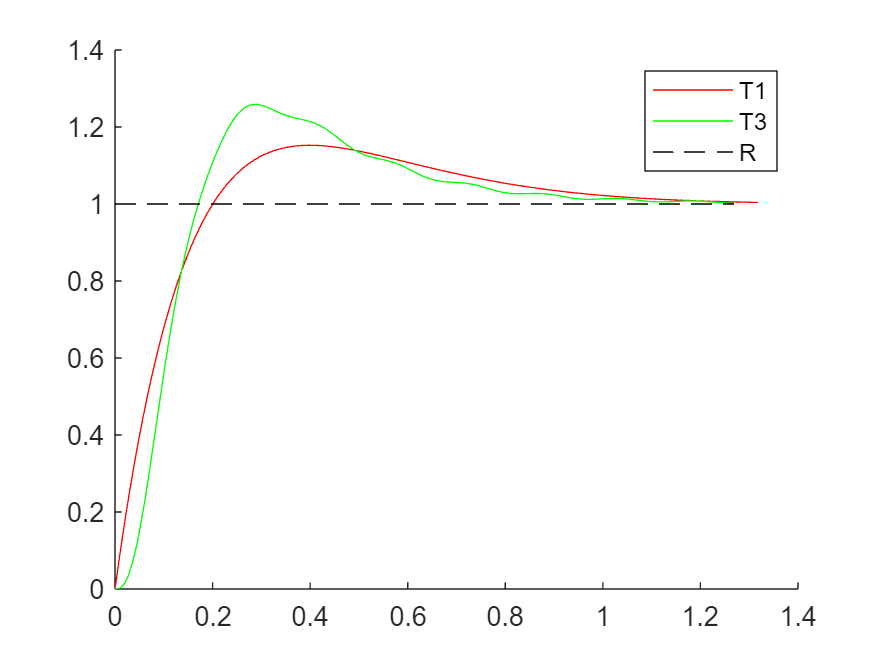

[y3, t3] = step(T3);
close all
figure(2)
hold on
plot(t1, y1, "r")
plot(t3, y3, "g")
plot([t3(1), t3(end)], [1, 1], "k--")
legend("T1", "T3", "R")

stepinfo(y3, t3, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.1079
    TransientTime: 0.7272
     SettlingTime: 0.7272
      SettlingMin: 0.9343
      SettlingMax: 1.2588
        Overshoot: 25.5930
       Undershoot: 0
             Peak: 1.2588
         PeakTime: 0.2863


16.34